# Project

## All value for 0° tilt

table with all data : solarwind

all0=sum(solarwind(:,2:4),2)

all0 = 17520×1 table
     sum  
    ______

         0
         0
         0
         0
         0
         0
         0
       114
    235.01
       193
    458.01
    461.01
    397.01
       254
        97
     28.33


% all the irradiance on the photovoltaic panel

mean0=mean(all0) %mean value of the 0° tilt of the panel

mean0 = table
     sum  
    ______

    179.49


mean0=double(mean0.sum(1))% energy produced per hour on average in W/m2

mean0 = 179.4916


dayHour=sum(solarwind(:,17) ~= 0);% number of hours when the sun is out
dayHour=double(dayHour.H_sun(1))

dayHour = 8562


allSum0=sum(all0)

allSum0 = table
       sum    
    __________

    3.1447e+06


allSum0=double(allSum0.sum(1))% global energy produced in W/m2

allSum0 = 3.1447e+06


meanDay0=allSum0/dayHour %energy produced per hour on average in W/m2 when the sun is out

meanDay0 = 367.2848

## All value for 35° tilt

all35=sum(solarwind(:,5:7),2)

all35 = 17520×1 table
     sum  
    ______

         0
         0
         0
         0
         0
         0
         0
    280.09
    427.66
    203.48
    832.85
    820.24
    689.63
     380.6
    104.06
     40.12



mean35=mean(all35) %mean value of the 35° tilt of the panel

mean35 = table
     sum  
    ______

    201.09


mean35=double(mean35.sum(1))% energy produced per hour on average in W/m2

mean35 = 201.0868


allSum35=sum(all35)

allSum35 = table
       sum   
    _________

    3.523e+06


allSum35=double(allSum35.sum(1))% global energy produced in W/m2

allSum35 = 3.5230e+06


meanDay35=allSum35/dayHour %energy produced per hour on average in W/m2 when the sun is out

meanDay35 = 411.4740

## All value for 40° tilt

all40=sum(solarwind(:,8:10),2)

all40 = 17520×1 table
     sum  
    ______

         0
         0
         0
         0
         0
         0
         0
     297.7
    446.02
    202.06
     866.5
    852.22
    715.87
    391.25
    103.59
     41.15



mean40=mean(all40) %mean value of the 40° tilt of the panel

mean40 = table
     sum  
    ______

    199.79


mean40=double(mean40.sum(1))% energy produced per hour on average in W/m2

mean40 = 199.7917


allSum40=sum(all40)

allSum40 = table
       sum    
    __________

    3.5004e+06


allSum40=double(allSum40.sum(1))% global energy produced in W/m2

allSum40 = 3.5004e+06


meanDay40=allSum40/dayHour %energy produced per hour on average in W/m2 when the sun is out

meanDay40 = 408.8240

## All value for 45° tilt

all45=sum(solarwind(:,11:13),2)

all45 = 17520×1 table
     sum  
    ______

         0
         0
         0
         0
         0
         0
         0
    313.28
     461.5
     199.9
    894.14
    878.35
    737.35
    399.64
    102.74
     41.99



mean45=mean(all45) %mean value of the 45° tilt of the panel

mean45 = table
     sum  
    ______

    197.35


mean45=double(mean45.sum(1))% energy produced per hour on average in W/m2

mean45 = 197.3463


allSum45=sum(all45)

allSum45 = table
       sum    
    __________

    3.4575e+06


allSum45=double(allSum45.sum(1))% global energy produced in W/m2

allSum45 = 3.4575e+06


meanDay45=allSum45/dayHour %energy produced per hour on average in W/m2 when the sun is out

meanDay45 = 403.8200

## All value for 90° tilt

all90=sum(solarwind(:,14:16),2)

all90 = 17520×1 table
     sum  
    ______

         0
         0
         0
         0
         0
         0
         0
    347.35
    457.48
    151.46
     850.1
    829.21
    698.25
    367.29
     79.93
     40.24



mean90=mean(all90) %mean value of the 90° tilt of the panel

mean90 = table
     sum 
    _____

    129.1


mean90=double(mean90.sum(1))% energy produced per hour on average in W/m2

mean90 = 129.1024


allSum90=sum(all90)

allSum90 = table
       sum    
    __________

    2.2619e+06


allSum90=double(allSum90.sum(1))% global energy produced in W/m2

allSum90 = 2.2619e+06


meanDay90=allSum90/dayHour %energy produced per hour on average in W/m2 when the sun is out

meanDay90 = 264.1759

## Best tilt = 35°

Test with the Crystalline Si technology with an average of 20% of efficiency, a tilt of 35°

the mean demand was 60 kWh in 2024

aTMD=(kWhFour*1000)/(meanDay35*0.2)% Area to match demand

aTMD = 733.0747

% if the panel produce 411 W/m2 the all day when the sun is up, we need 733
% m2 of solar panel

prod35=meanDay35*0.2

prod35 = 82.2948

newProd3517=meanDay35*0.2*(0.95^17)%apres 17 ans

newProd3517 = 34.4091

newProd35=meanDay35*0.2*(0.95^25)

newProd35 = 22.8277

newATMD=(kWhFour*1000)/(newProd35)%m² de panneau solaire apres 25 ans, perte de 0.5% par an d'efficacité pour repondre a la demande mean

newATMD = 2.6428e+03

## Graphe representant la perte d'efficacité des panneau solaires

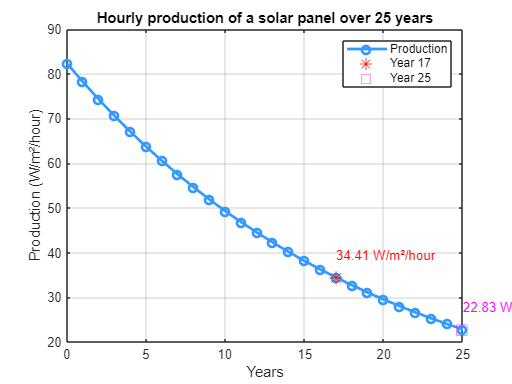

% Base data
meanDay35 = 411.47; % W/m²/day
initial_efficiency = 0.20;
degradation_5years = 0.95;

% Year vector
years = 0:25;

% Efficiency calculation using your formula
efficiency = initial_efficiency * (degradation_5years) .^ years;

% Production per day in W/m² (still using daily value)
production_per_day = meanDay35 * efficiency;

% Specific year calculations (like in your example)
prod_year_17 = meanDay35 * 0.2 * (0.95^17);
prod_year_25 = meanDay35 * 0.2 * (0.95^25);

% Plot
figure;
plot(years, production_per_day, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 1]);
hold on;

% Highlight points for year 17 and 25
plot(17, prod_year_17, 'r*', 'MarkerSize', 10, 'DisplayName', 'Year 17');
plot(25, prod_year_25, 'ms', 'MarkerSize', 10, 'DisplayName', 'Year 25');

% Annotations
text(17, prod_year_17 + 5, sprintf('%.2f W/m²/hour', prod_year_17), 'Color', 'red');
text(25, prod_year_25 + 5, sprintf('%.2f W/m²/hour', prod_year_25), 'Color', 'magenta');

% Formatting
title("Hourly production of a solar panel over 25 years");
xlabel("Years");
ylabel("Production (W/m²/hour)");
grid on;
legend("Production", "Year 17", "Year 25", 'Location', 'northeast');

the peak demand was 110 kWh

aTMPD=(kWhFourMax*1000)/(meanDay35*0.2)% Area to match peak demand

aTMPD = 1.3464e+03

% if the panel produce 411 W/m2 the all day when the sun is up, we need
% 1346 m2 of solar panel

## half of 35°

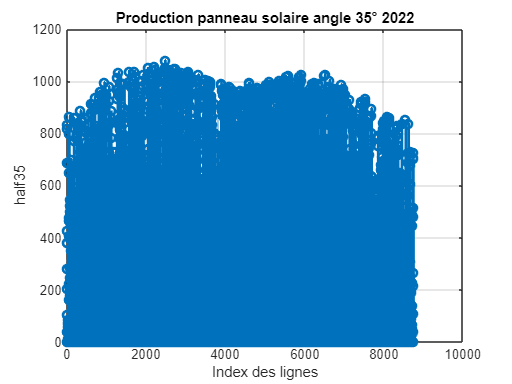

n = floor(height(all35) / 2); % Trouver la moitié (arrondi inférieur)
half35 = all35(1:n, :); % Sélectionner les premières n lignes
Thalf35 = all35(n:height(all35), :);


figure;
plot(1:length(half35.sum), half35.sum, '-o', 'LineWidth', 2); 

xlabel('Index des lignes');
ylabel('half35');
title('Production panneau solaire angle 35° 2022');
grid on;

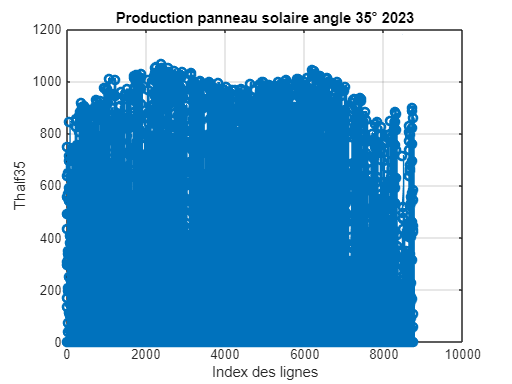


figure;
plot(1:length(Thalf35.sum), Thalf35.sum, '-o', 'LineWidth', 2); 

xlabel('Index des lignes');
ylabel('Thalf35');
title('Production panneau solaire angle 35° 2023');
grid on;

## power output after 25 years

temp=newProd35*300

temp = 6.8483e+03

temp=prod35*300

temp = 2.4688e+04